# Разметка частотной оси

Данный файл призван, чтобы правильно образмеривать ось частот для различных вариантов отображения спектра

## Число отсчетов - четное

Инициализация параметров:

fs = 1e3;                           % частота дискретизации
N  = 10;                            % кол-во отсчетов входного сигнала
S  = [3 1 1 5 4 2 4 5 1 1];         % произвольный спектр сигнала

### Односторонний спектр (полный)

Данный спектр отображает все спектральные составляющие на промежутке [0; fs-fs/N]

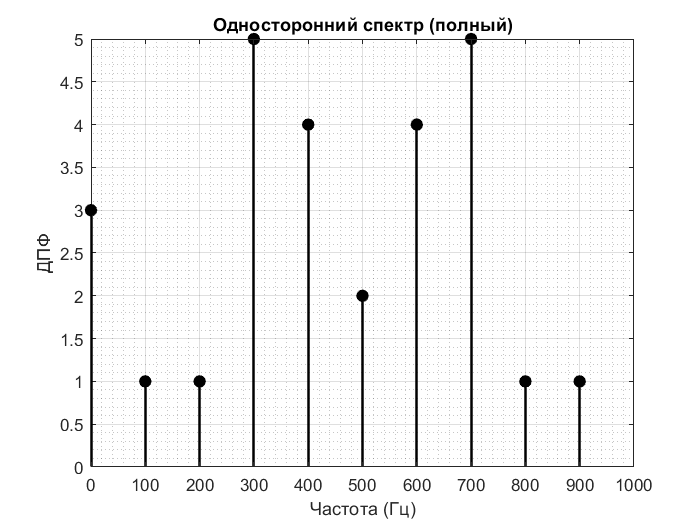

f = (0:N-1)*fs/N;                   % вектор частот

stem(f,S,'-k','filled','LineWidth',1.5);
grid on; grid minor; xlim([0 fs]); title('Односторонний спектр (полный)');
xlabel('Частота (Гц)'); ylabel('ДПФ');

### Односторонний спектр (половина)

Данный спектр отображает все спектральные составляющие на промежутке [0; fs/2]

Данный способ отображения спектра является наиболее предпочтительным, т.к. из-за умножения на 2, показывает реальные амплитуды гармоник сигнала

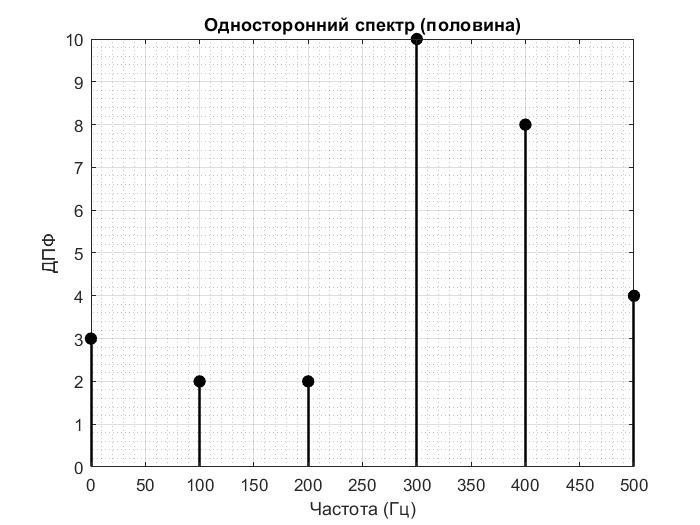

f1    = f(1:N/2+1);                 % уполовинивание вектора частот
S1    = 2*S(1:N/2+1);               % уполовинивание спектра
S1(1) = S(1);                       % неизменность постоянной составляющей

stem(f1,S1,'-k','filled','LineWidth',1.5);
grid on; grid minor; xlim([0 fs/2]); title('Односторонний спектр (половина)');
xlabel('Частота (Гц)'); ylabel('ДПФ');

### Двусторонний спектр

Данный спектр отображает все спектральные составляющие на промежутке [-fs/2; fs/2]

При этом, если впоследствии потребуется размножать данный спектр, то необходимо закомментировать строки №17, 19 и откомментировать строку №16

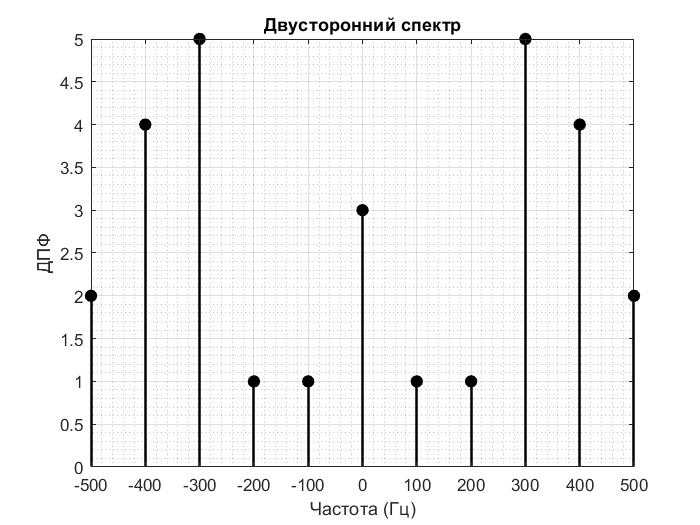

% f2 = (-N/2:N/2-1)*fs/N;             % формирование вектора частот
f2 = (-N/2:N/2)*fs/N;               % формирование вектора частот
S2 = fftshift(S);                   % формирование двустороннего спектра
S2 = [S2 S2(1)];                    % добавление отсчета на частоте Найквиста

stem(f2,S2,'-k','filled','LineWidth',1.5);
grid on; grid minor; xlim([-fs/2 fs/2]); title('Двусторонний спектр');
xlabel('Частота (Гц)'); ylabel('ДПФ');

## Число отсчетов - нечетное

Инициализация параметров:

fs = 1e3;                           % частота дискретизации
N  = 11;                            % кол-во отсчетов входного сигнала
S  = [3 1 1 5 4 2 2 4 5 1 1];       % произвольный спектр сигнала

### Односторонний спектр (полный)

Данный спектр отображает все спектральные составляющие на промежутке [0; fs-fs/N]

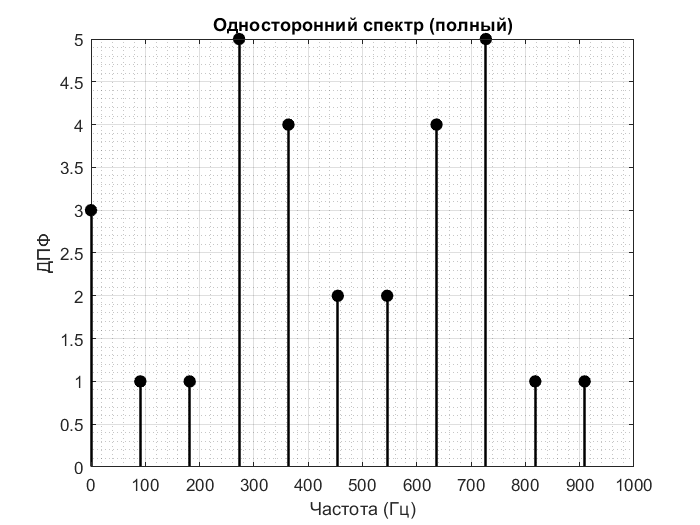

f = (0:N-1)*fs/N;                   % вектор частот

stem(f,S,'-k','filled','LineWidth',1.5);
grid on; grid minor; xlim([0 fs]); title('Односторонний спектр (полный)');
xlabel('Частота (Гц)'); ylabel('ДПФ');

### Односторонний спектр (половина)

Данный спектр отображает все спектральные составляющие на промежутке [0; fs/2-fs/(2N)]

Данный способ отображения спектра является наиболее предпочтительным, т.к. из-за умножения на 2, показывает реальные амплитуды гармоник сигнала

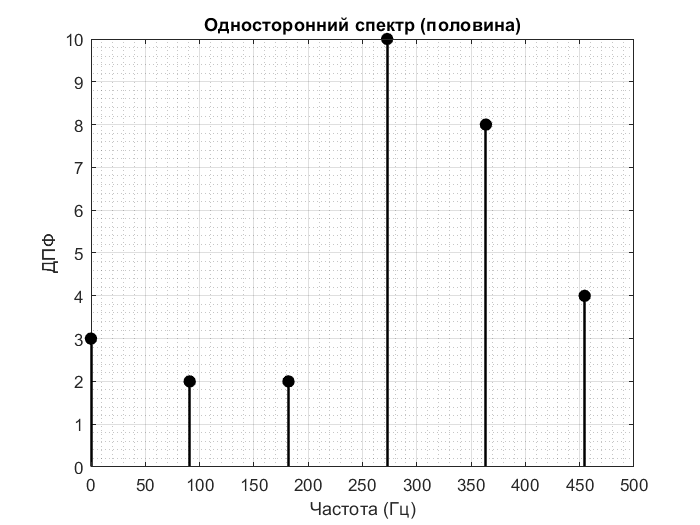

f1    = f(1:ceil(N/2));             % уполовинивание вектора частот
S1    = 2*S(1:ceil(N/2));           % уполовинивание спектра
S1(1) = S(1);                       % неизменность постоянной составляющей

stem(f1,S1,'-k','filled','LineWidth',1.5);
grid on; grid minor; xlim([0 fs/2]); title('Односторонний спектр (половина)');
xlabel('Частота (Гц)'); ylabel('ДПФ');

### Двусторонний спектр

Данный спектр отображает все спектральные составляющие на промежутке [-fs/2+fs/(2N); fs/2-fs/(2N)]

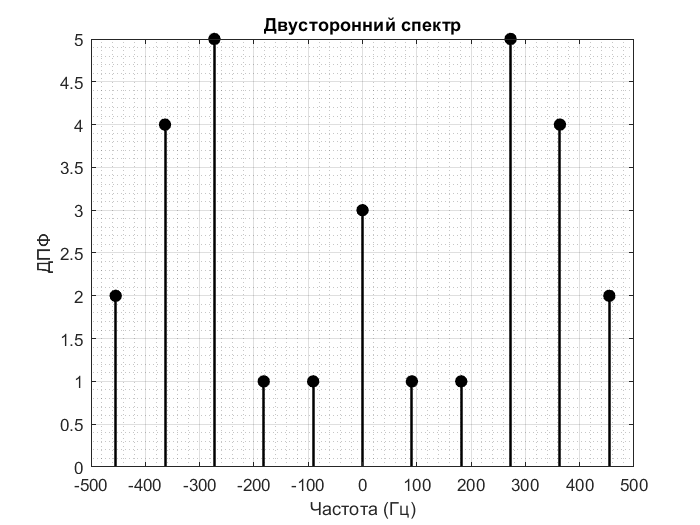

f2 = (-floor(N/2):floor(N/2))*fs/N; % формирование вектора частот
S2 = fftshift(S);                   % формирование двустороннего спектра

stem(f2,S2,'-k','filled','LineWidth',1.5);
grid on; grid minor; xlim([-fs/2 fs/2]); title('Двусторонний спектр');
xlabel('Частота (Гц)'); ylabel('ДПФ');

## Заключение

Резюмируя все вышепоказанное, можно сказать, что лучше выбирать кол-во отсчетов четным числом, т.к.:

- спектр в этом случае обязательно попадает на частоту Найквиста

- в этом случае число отсчетов может оказаться равным $N = 2^x$, что позволит использовать алгоритм БПФ и сократит объем вычислений

Самое тяжелое представляет из себя процесс формирования двустороннего спектра, но его достаточно легко понять, рассмотрев следующие графики:

$N$ - четное

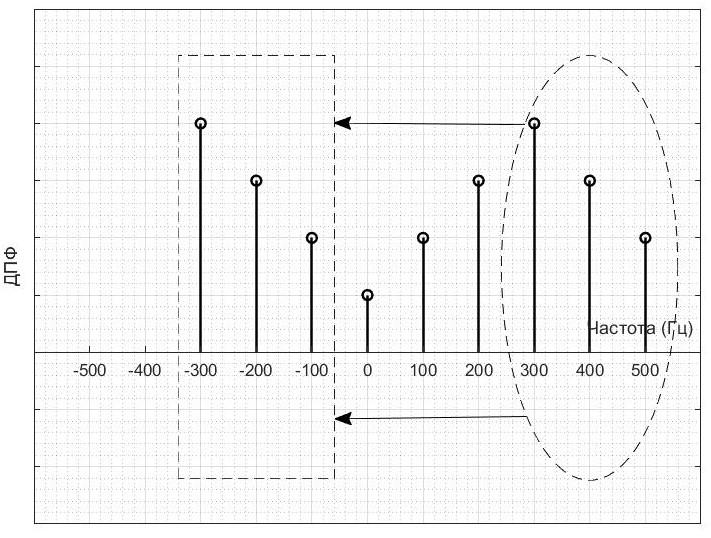

$N$ - нечетное